scores(:,:,:,1) = scores(:,:,:,1)*100;

disp(size(scores));

    50    41    16     5





% Define metric names for clarity
metricNames = {'Accuracy','Sensitivity', 'Specificity', 'Precision', 'F1-Score'};
thresholds = [0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2];
beta_values =   [0, 0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2, 2.125, 2.25, 2.375, 2.5, 2.625, 2.75, 2.875, 3, 3.125, 3.25, 3.375, 3.5, 3.625, 3.75, 3.875, 4, 4.125,4.25,4.375,4.5,4.625,4.75,4.875,5];
rng_list = (1:10);

% Preallocate matrix for mean metrics
metricsMeans = zeros(size(scores,2),size(scores, 3), length(metricNames));

% Loop over beta values
for j = 1 : size(scores,2)
    for i = 1:size(scores, 3)
        % Compute mean and standard deviation across seeds (dimension 1)
        means = squeeze(mean(scores(1:10,j, i, :), 1)); % 1 x 4 vector
        stds = squeeze(std(scores(1:10,j, i, :), [], 1)); % 1 x 4 vector
        
        % Store means and display results
        metricsMeans(j, i, :) = means;

    end
end



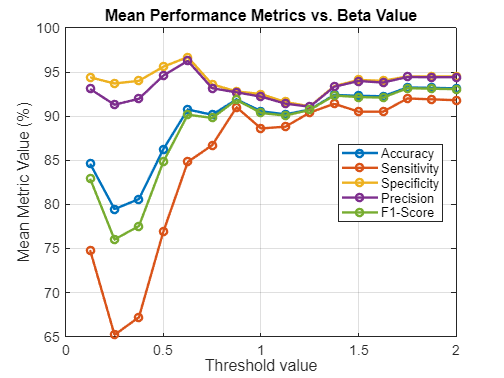

% Plot mean metrics vs. beta values
figure;
plot(thresholds, squeeze(metricsMeans(16,:,:)), '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Threshold value');
ylabel('Mean Metric Value (%)');
title('Mean Performance Metrics vs. Beta Value');
legend(metricNames, 'Location', 'best');
grid on;
set(gca, 'FontSize', 12);

maxThresholds = zeros(length(beta_values),1);
maxThresholdsIdx = zeros(length(beta_values),1);
for i = 1 : length(beta_values)
    results = squeeze(metricsMeans(i,:,5));
    [maxValue, idx] = max(results);
    maxThresholdsIdx(i) = idx;
    maxThresholds(i) = maxValue;
end

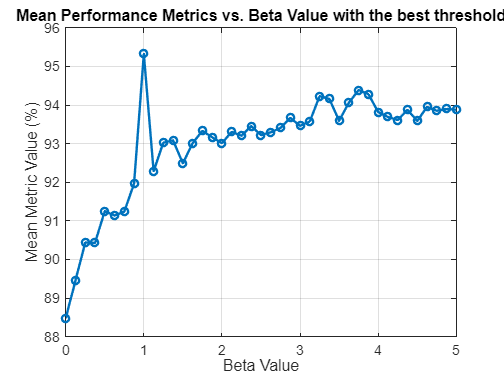

% Plot mean metrics vs. beta values
figure;
plot(beta_values, squeeze(maxThresholds), '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Beta Value');
ylabel('Mean Metric Value (%)');
title('Mean Performance Metrics vs. Beta Value with the best threshold');
grid on;
set(gca, 'FontSize', 12);

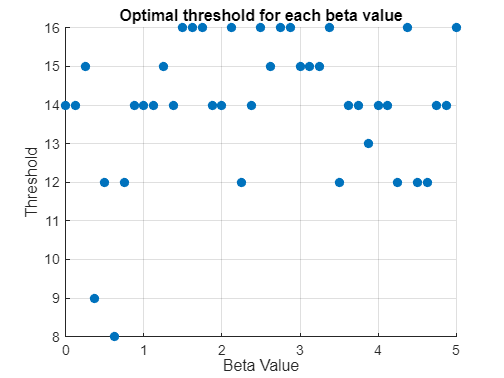

% Plot mean metrics vs. beta values as a scatter plot
figure;
scatter(beta_values, squeeze(maxThresholdsIdx), 60, 'filled');
xlabel('Beta Value');
ylabel('Threshold');
title('Optimal threshold for each beta value');
grid on;
set(gca, 'FontSize', 12);

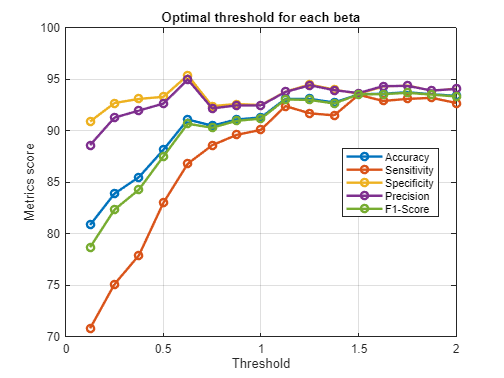



% Define metric names for clarity

% Preallocate matrix for mean metrics
metricsMeans = zeros(size(scores, 3), length(metricNames));

means = zeros();
% Loop over beta values
for i = 1:size(scores, 3)
    % Compute mean and standard deviation across seeds (dimension 1)
    means = squeeze(mean(scores(1:10,34, i, :), 1)); % 1 x 4 vector
    stds = squeeze(std(scores(1:10,34, i, :), [], 1)); % 1 x 4 vector
    
    % Store means and display results
    metricsMeans(i, :) = means;

end

% Plot mean metrics vs. beta values
figure;
plot(thresholds, metricsMeans, '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Threshold');
ylabel('Metrics score');
title('Optimal threshold for each beta');
legend(metricNames, 'Location', 'best');
grid on;

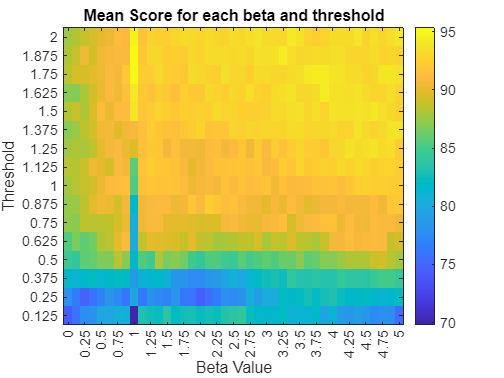

metricsMeans = zeros(size(scores, 3), size(scores,2));

for i = 1:size(scores, 3)
    % Compute mean and standard deviation across seeds (dimension 1)
    means = squeeze(mean(scores(1:10,:, i, 5), 1)); % 1 x 4 vector
    stds = squeeze(std(scores(1:10,:, i, 5), [], 1)); % 1 x 4 vector
    
    % Store means and display results
    metricsMeans(i, :) = means;

end

% Plot heatmap
figure;
imagesc(metricsMeans);
colorbar;

% Fix y-axis direction
set(gca, 'YDir', 'normal');

% Axis labels and title
xlabel('Beta Value');
ylabel('Threshold');
title('Mean Score for each beta and threshold');
set(gca, 'FontSize', 12);
set(colorbar, 'FontSize', 12); % Optional: consistent font size

% Set ticks and labels
skip = 2;
xticks(1:skip:length(beta_values));
xticklabels(string(beta_values(1:skip:end)));
yticks(1:length(thresholds));
yticklabels(string(thresholds));